**1.2.1.1**

setting the parameters of the exercise:

A1 = 1 ; f1 = 1;
A2 = 2 ; f2 = 2.5;
Ac = 2 ; fc = 25;

A = 3 ;

Kf = 1 ; 
fs = 3.34 * 1e3 

fs = 3340

K1_dB = db(10) ; K2_dB = db(1/sqrt(10))

K2_dB = -10

setting the time domain interval and the freq axis

t = -3:1/fs:3

t =    -3.0000   -2.9997   -2.9994   -2.9991   -2.9988   -2.9985   -2.9982   -2.9979   -2.9976   -2.9973   -2.9970   -2.9967   -2.9964   -2.9961   -2.9958   -2.9955   -2.9952   -2.9949   -2.9946   -2.9943   -2.9940   -2.9937   -2.9934   -2.9931   -2.9928   -2.9925   -2.9922   -2.9919   -2.9916   -2.9913   -2.9910   -2.9907   -2.9904   -2.9901   -2.9898   -2.9895   -2.9892   -2.9889   -2.9886   -2.9883   -2.9880   -2.9877   -2.9874   -2.9871   -2.9868   -2.9865   -2.9862   -2.9859   -2.9856   -2.9853


t1 = 4.8 *1e-3

t1 = 0.0048

t2 = 14.4 *1e-3

t2 = 0.0144


N = length(t)

N = 20041

f = -N/2 : N/2 -1 * (fs/N)

f = 1.0e+04 *

   -1.0021   -1.0019   -1.0018   -1.0017   -1.0016   -1.0015   -1.0014   -1.0013   -1.0012   -1.0011   -1.0010   -1.0010   -1.0009   -1.0008   -1.0007   -1.0006   -1.0005   -1.0004   -1.0003   -1.0002   -1.0001   -1.0000   -0.9999   -0.9998   -0.9997   -0.9996   -0.9994   -0.9993   -0.9992   -0.9991   -0.9990   -0.9990   -0.9989   -0.9988   -0.9987   -0.9986   -0.9984   -0.9983   -0.9982   -0.9981   -0.9980   -0.9980   -0.9979   -0.9978   -0.9977   -0.9976   -0.9974   -0.9973   -0.9972   -0.9971


setting the time stamps in vectors and creating the signals in time:

vm = @(t) A1 * sin(2*pi*f1*t) + A2 * sin(2*pi*f2*t) ;
vc = @(t) Ac * cos(2*pi*fc*t) ;

Vm = vm(t)

Vm =    -0.0000   -0.0075   -0.0150   -0.0226   -0.0301   -0.0376   -0.0451   -0.0527   -0.0602   -0.0677   -0.0752   -0.0827   -0.0902   -0.0977   -0.1053   -0.1128   -0.1203   -0.1278   -0.1353   -0.1427   -0.1502   -0.1577   -0.1652   -0.1727   -0.1801   -0.1876   -0.1951   -0.2025   -0.2100   -0.2174   -0.2248   -0.2323   -0.2397   -0.2471   -0.2545   -0.2619   -0.2693   -0.2767   -0.2841   -0.2915   -0.2988   -0.3062   -0.3136   -0.3209   -0.3282   -0.3356   -0.3429   -0.3502   -0.3575   -0.3648


Vc = vc(t)

Vc =     2.0000    1.9978    1.9912    1.9801    1.9647    1.9450    1.9209    1.8926    1.8601    1.8235    1.7829    1.7383    1.6899    1.6377    1.5819    1.5226    1.4600    1.3941    1.3252    1.2533    1.1786    1.1013    1.0216    0.9397    0.8556    0.7697    0.6821    0.5929    0.5025    0.4109    0.3184    0.2253    0.1316    0.0376   -0.0564   -0.1504   -0.2439   -0.3370   -0.4293   -0.5207   -0.6109   -0.6997   -0.7870   -0.8726   -0.9562   -1.0378   -1.1170   -1.1938   -1.2679   -1.3392


ploting the signal and the carrier signal in time:

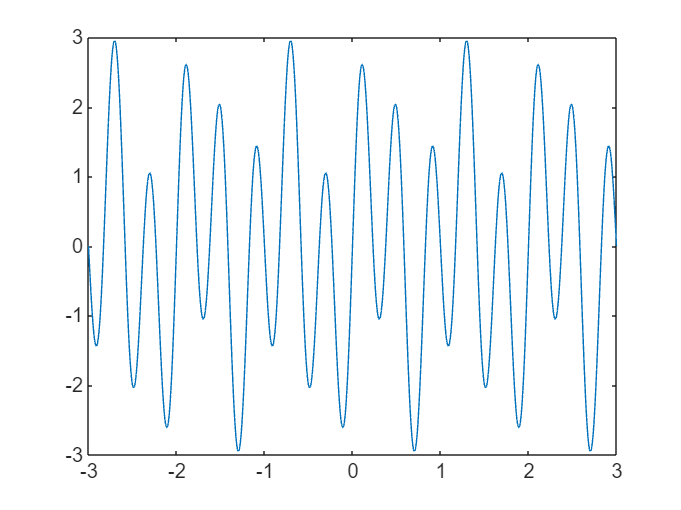

plot(t,Vm)

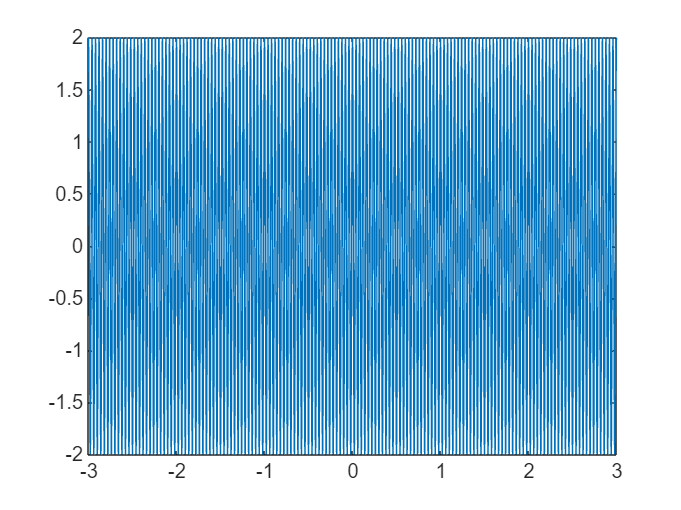

plot(t,Vc)

**1.2.1.2**

creating **suppressed** carrier Modulation:

function vsc = DSB_SC_Mod(vm,vc)
    vsc = vm .* vc ;
end 

actively modulating the signal:

V_T1 = DSB_SC_Mod(Vm,Vc);

plotting result:

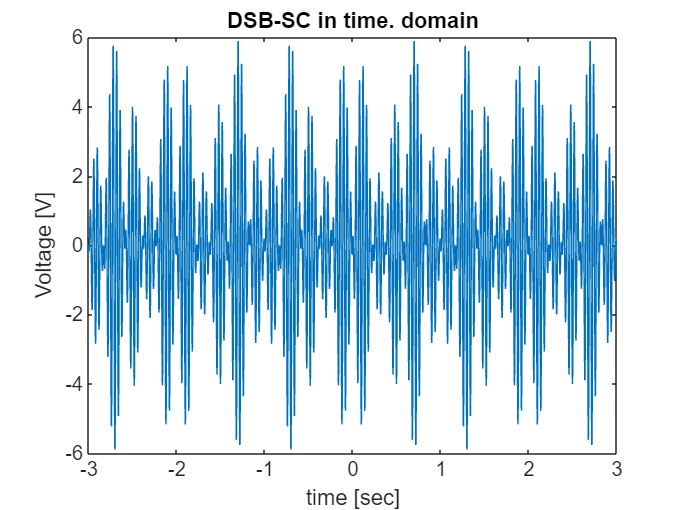

plot(t,V_T1)
title("DSB-SC in time. domain")
xlabel("time [sec]")
ylabel("Voltage [V]")

calculating the fourier transform of the modulated signal:

explanation for normalization : we normalize by fs because matlab does not have any sense of units of time, it treat all samples to be in a distance of 1 unit which ever it might be.

since the unit of measurement is [sec] and the distance between each 2 measurements is 1/fs [sec] we account for that in the normalization we perform.

Vsc_w = fftshift(fft(V_T1,N))/( fs)

Vsc_w =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


plot(f, abs(Vsc_w))

fs/N 

ans = 0.1667


f_max = fc + max([f1,f2])

f_max = 27.5000

f_min = fc - max([f1,f2])

f_min = 22.5000


theta_max = f_max / fs * N

theta_max = 165.0082

theta_min = f_min / fs * N

theta_min = 135.0067

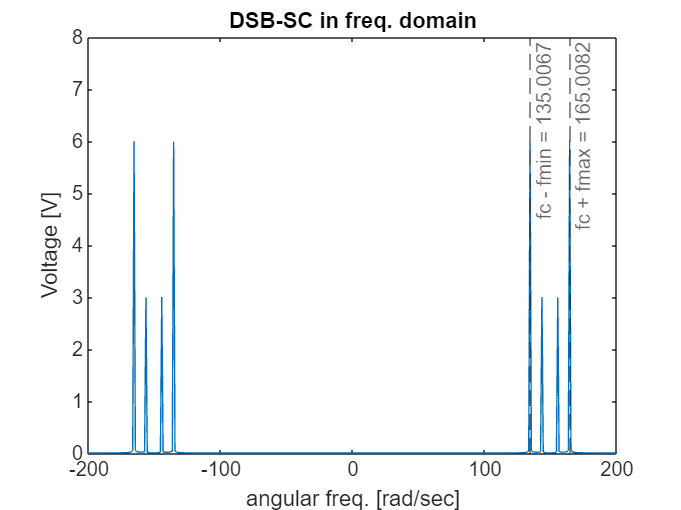


xline(theta_max,"--",Label="fc + fmax = " + theta_max)
xline(theta_min,"--",Label="fc - fmin = " + theta_min)

lim = 200;
xlim([-lim lim])
ylim([0 8])
title("DSB-SC in freq. domain")
xlabel("angular freq. [rad/sec]")
ylabel("Voltage [V]")

**1.2.1.3**

creating **large** carrier Modulation:

function vlc = DSB_LC_Mod(vm,vc,A)
    vlc = (A+vm).* vc ;
end 

actively modulating the signal:

V_T2 = DSB_LC_Mod(Vm,Vc,A);

plotting result:

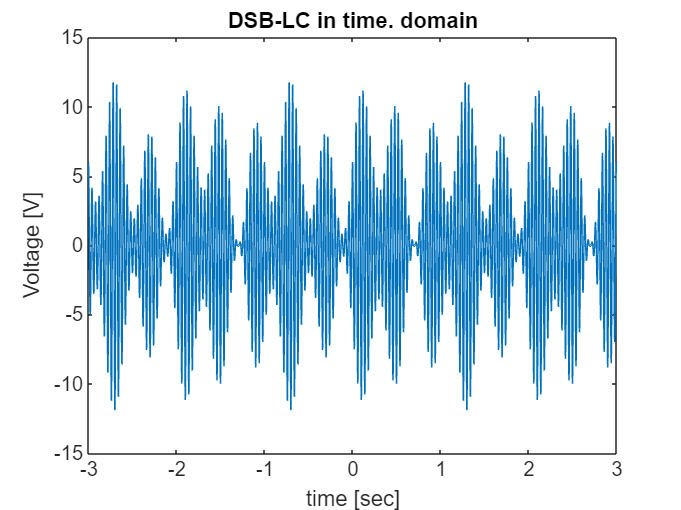

plot(t,V_T2)
title("DSB-LC in time. domain")
xlabel("time [sec]")
ylabel("Voltage [V]")

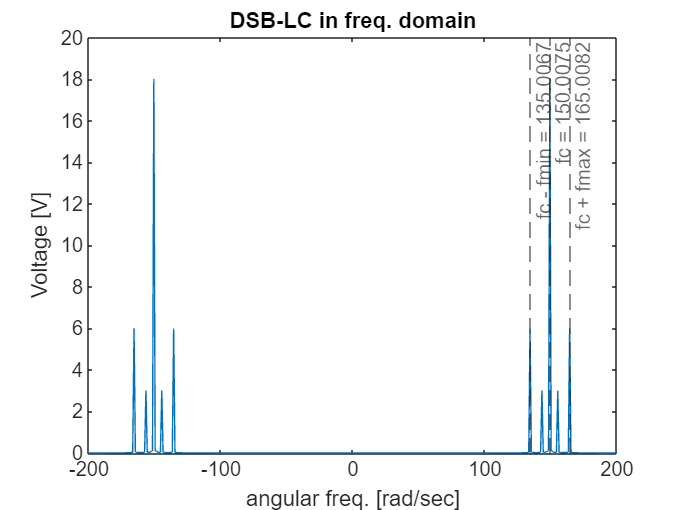

Vsc_w = fftshift(fft(V_T2,N))/( fs);
plot(f, abs(Vsc_w))

f_max = fc + max([f1,f2]);
f_min = fc - max([f1,f2]);

theta_max = f_max / fs * N;
theta_c = fc / fs * N;
theta_min = f_min / fs * N;

xline(theta_max,"--",Label="fc + fmax = " + theta_max)
xline(theta_c,"--",Label="fc = " + theta_c)
xline(theta_min,"--",Label="fc - fmin = " + theta_min)

lim = 200;
xlim([-lim lim])
ylim([0 20])
title("DSB-LC in freq. domain")
xlabel("angular freq. [rad/sec]")
ylabel("Voltage [V]")

**1.2.1.4**

creating the function for FM modulation:

FM_Mod = @(t,signal) Ac * cos(2*pi*fc*t + 2*pi*Kf*cumtrapz(signal)) ;

actively modulating the signal

Vc_fm= FM_Mod(t,Vm)

Vc_fm =     2.0000    1.9995    2.0000    1.9949    1.9640    1.8747    1.6851    1.3512    0.8416    0.1590   -0.6336   -1.3944   -1.9089   -1.9424   -1.3478   -0.2028    1.1018    1.9352    1.7316    0.4374   -1.2149   -2.0000   -1.1309    0.8035    1.9908    1.0601   -1.1234   -1.9484   -0.1886    1.8649    1.1263   -1.4219   -1.5852    1.0746    1.7303   -1.0111   -1.6716    1.2558    1.3602   -1.6972   -0.6306    1.9986   -0.5747   -1.5715    1.7717    0.0297   -1.7564    1.7430   -0.1854   -1.4715


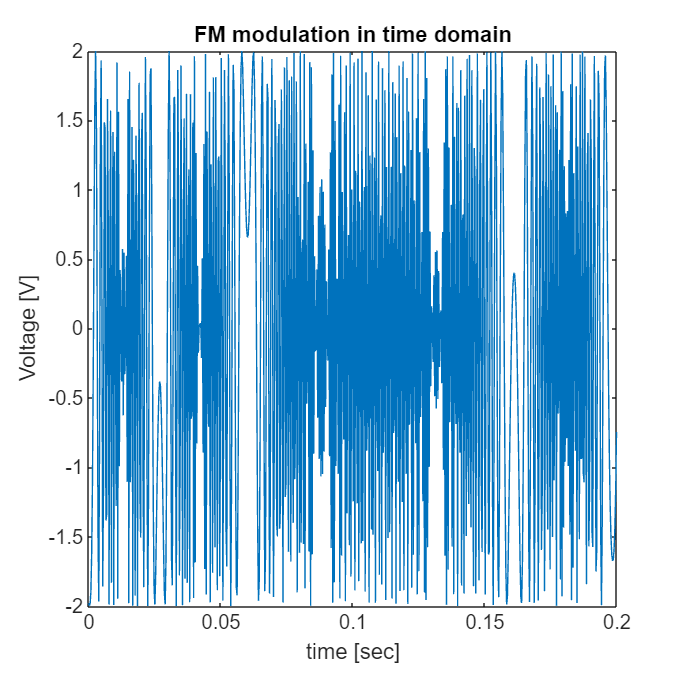

figure('Position', [100, 100, 1200, 1200]); % [left, bottom, width, height]
plot(t,Vc_fm)
xlim([0  0.2])
title("FM modulation in time domain")
xlabel("time [sec]")
ylabel("Voltage [V]")

**1.2.2**

K1 = 10^(K1_dB/20);
K2 = 10^(K2_dB/20);

P_ch = mean(V_T1.^2); 

B_bw = 5; 

SNRs_dB = [-10, 0, 10];

z = zeros(3, length(t)); 

for i = 1:3
    SNR_lin = 10^(SNRs_dB(i)/10);
    Ni = P_ch / (B_bw * SNR_lin);
    noise_var = Ni / 2;
    z(i, :) = sqrt(noise_var) * randn(1, length(t));
end

h_ch = zeros(1, length(t));

[~, idx_0] = min(abs(t)); 

idx_t1 = round(t1 * fs);
idx_t2 = round(t2 * fs);


calculate indicies:

if (idx_0 + idx_t1) <= length(t)
    h_ch(idx_0 + idx_t1) = K1 * fs; 
end
if (idx_0 + idx_t2) <= length(t)
    h_ch(idx_0 + idx_t2) = K2 * fs;
end

Generate Received Signals (No Channel):

x_r1 = V_T1 + z(1, :);
x_r2 = V_T1 + z(2, :);
x_r3 = V_T1 + z(3, :);

Generate Received Signal (With Channel):

v_distorted = conv(V_T1, h_ch, 'same') / fs;
x_r3_ch = v_distorted + z(3, :);


plot results:

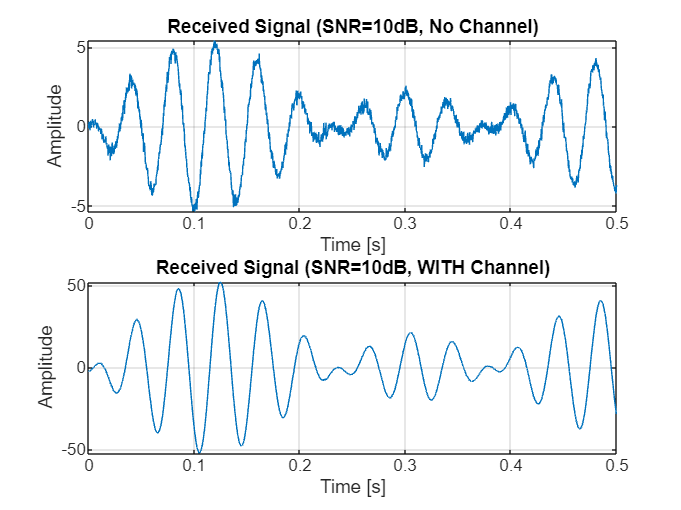

figure;
subplot(2,1,1);
plot(t, x_r3);
title('Received Signal (SNR=10dB, No Channel)');
xlabel('Time [s]'); ylabel('Amplitude');
xlim([0 0.5]); grid on;

subplot(2,1,2);
plot(t, x_r3_ch);
title('Received Signal (SNR=10dB, WITH Channel)');
xlabel('Time [s]'); ylabel('Amplitude');
xlim([0 0.5]); grid on;

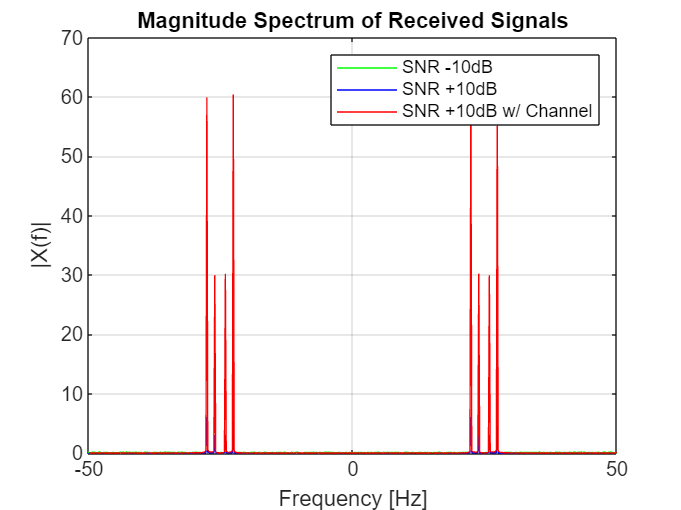


% Plot Frequency Domain (Magnitude)
% Generate f axis
f = (-length(t)/2 : length(t)/2 - 1) * (fs/length(t));

X_r1_w = fftshift(fft(x_r1)) / fs;
X_r2_w = fftshift(fft(x_r2)) / fs;
X_r3_w = fftshift(fft(x_r3)) / fs;
X_r3_ch_w = fftshift(fft(x_r3_ch)) / fs;

figure;
plot(f, abs(X_r1_w), 'g', 'DisplayName', 'SNR -10dB'); hold on;
plot(f, abs(X_r3_w), 'b', 'DisplayName', 'SNR +10dB'); 
plot(f, abs(X_r3_ch_w), 'r', 'DisplayName', 'SNR +10dB w/ Channel');
hold off;
legend;
title('Magnitude Spectrum of Received Signals');
xlabel('Frequency [Hz]'); ylabel('|X(f)|');
xlim([-50 50]); grid on;

**1.2.3**

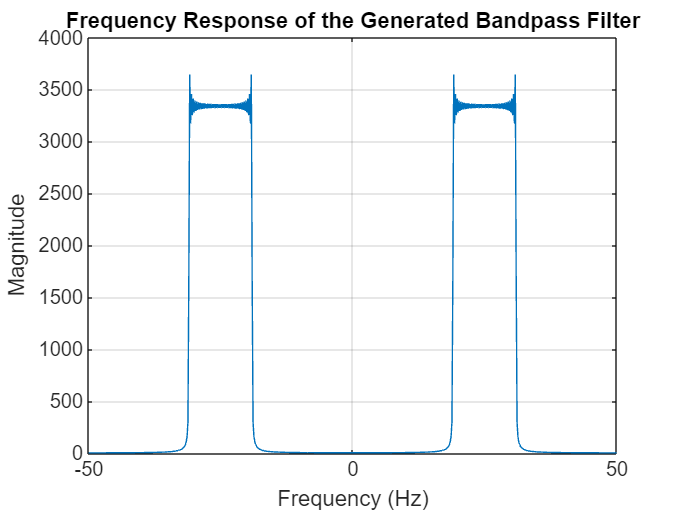

wp = 1.2 * 2 * pi * B_bw;

h_lpf = sin(wp * t) ./ (pi * t);
h_lpf(t == 0) = wp / pi;

h_bpf = 2 * h_lpf .* cos(2 * pi * fc * t);

H_BPF = fftshift(fft(h_bpf));
f_axis = linspace(-fs/2, fs/2, length(t));

figure;
plot(f_axis, abs(H_BPF));
title('Frequency Response of the Generated Bandpass Filter');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
xlim([-50 50]);
grid on;

Ts = 1/fs

Ts = 2.9940e-04

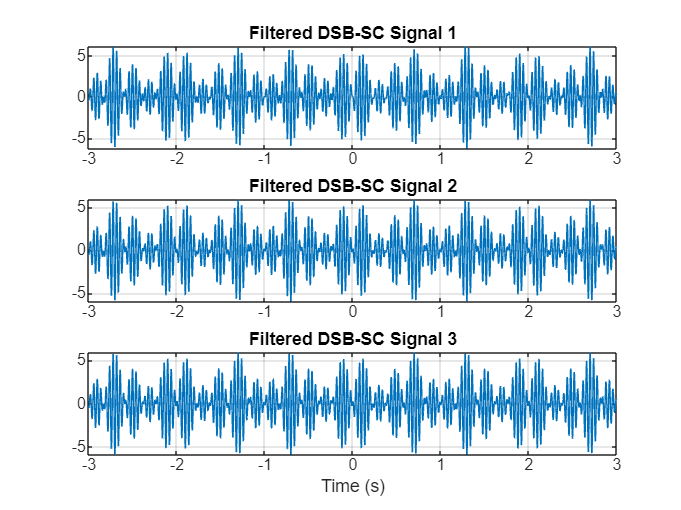

x_L1_SC = conv(x_r1, h_bpf, 'same') * Ts;
x_L2_SC = conv(x_r2, h_bpf, 'same') * Ts;
x_L3_SC = conv(x_r3, h_bpf, 'same') * Ts;

figure;
subplot(3,1,1); plot(t, x_L1_SC); title('Filtered DSB-SC Signal 1'); grid on;
subplot(3,1,2); plot(t, x_L2_SC); title('Filtered DSB-SC Signal 2'); grid on;
subplot(3,1,3); plot(t, x_L3_SC); title('Filtered DSB-SC Signal 3'); grid on;
xlabel('Time (s)');

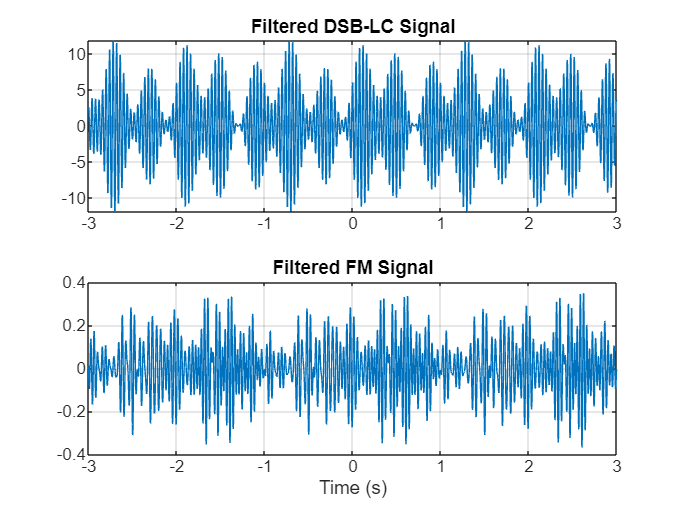

x_L2_LC = conv(V_T2, h_bpf, 'same') * Ts;
x_L2_FM = conv(Vc_fm, h_bpf, 'same') * Ts;

figure;
subplot(2,1,1); plot(t, x_L2_LC); title('Filtered DSB-LC Signal'); grid on;
subplot(2,1,2); plot(t, x_L2_FM); title('Filtered FM Signal'); grid on;
xlabel('Time (s)');

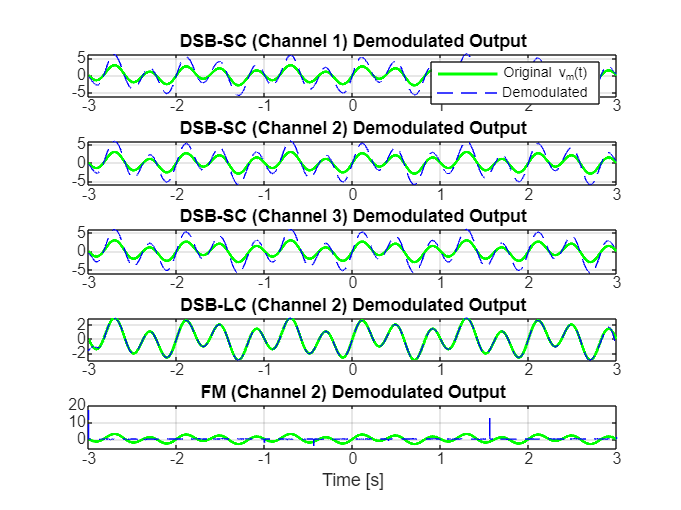

% DSB-SC Demodulation (Coherent Detection)
x_mix1 = x_L1_SC .* (2 * cos(2 * pi * fc * t));
x_d1_SC = conv(x_mix1, h_lpf, 'same') * Ts;

x_mix2 = x_L2_SC .* (2 * cos(2 * pi * fc * t));
x_d2_SC = conv(x_mix2, h_lpf, 'same') * Ts;

x_mix3 = x_L3_SC .* (2 * cos(2 * pi * fc * t));
x_d3_SC = conv(x_mix3, h_lpf, 'same') * Ts;

% DSB-LC Demodulation (Envelope Detector)
x_hat = imag(hilbert(x_L2_LC));
envelope = sqrt(x_L2_LC.^2 + x_hat.^2);
x_d2_LC = (envelope - A * Ac) / Ac;

% FM Demodulation
freq_dev = 50; % Assuming standard deviation, adjust if given in previous section
x_d2_FM = fmdemod(x_L2_FM, fc, fs, freq_dev);

% Ensure all signals match the length of t
L = length(t);

% Trim signals if they are longer than t
x_d1_SC = x_d1_SC(1:L);
x_d2_SC = x_d2_SC(1:L);
x_d3_SC = x_d3_SC(1:L);
x_d2_LC = x_d2_LC(1:L);
x_d2_FM = x_d2_FM(1:L);
vm      = vm(1:L); % Just in case vm is different

figure('Name', 'Demodulated Signals vs Original Message');

% --- Plot 1: DSB-SC Channel 1 ---
subplot(5,1,1);
plot(t, Vm, 'g', 'LineWidth', 1.5); hold on;
plot(t, x_d1_SC, 'b--');
title('DSB-SC (Channel 1) Demodulated Output');
legend('Original v_m(t)', 'Demodulated');
grid on; hold off;

% --- Plot 2: DSB-SC Channel 2 ---
subplot(5,1,2);
plot(t, Vm, 'g', 'LineWidth', 1.5); hold on;
plot(t, x_d2_SC, 'b--');
title('DSB-SC (Channel 2) Demodulated Output');
grid on; hold off;

% --- Plot 3: DSB-SC Channel 3 ---
subplot(5,1,3);
plot(t, Vm, 'g', 'LineWidth', 1.5); hold on;
plot(t, x_d3_SC, 'b--');
title('DSB-SC (Channel 3) Demodulated Output');
grid on; hold off;

% --- Plot 4: DSB-LC Channel 2 ---
subplot(5,1,4);
plot(t, Vm, 'g', 'LineWidth', 1.5); hold on;
plot(t, x_d2_LC, 'b--');
title('DSB-LC (Channel 2) Demodulated Output');
grid on; hold off;

% --- Plot 5: FM Channel 2 ---
subplot(5,1,5);
plot(t, Vm, 'g', 'LineWidth', 1.5); hold on;
plot(t, x_d2_FM, 'b--');
title('FM (Channel 2) Demodulated Output');
xlabel('Time [s]');
grid on; hold off;